#### General parameters 

These are the same 'options' used for the filtering and segmentation

opts.orig_file_dir = "../physionet.org/textdata/";
opts.abp_ann_dir = '../physionet.org/abp_ann/';
opts.segmented_file_dir = "../physionet.org/segmented_data/";
opts.clear_segmented_dir = false; %delete all existing files in segmented file directory
opts.segmented_abp_dir = "../physionet.org/segmented_abp_beats/";

opts.first_record_process = 180;
opts.last_record_process = 185; %use -1 to process all

opts.apply_filter = false;
opts.samp_freq = 125;
opts.filter.type = 'low';
opts.filter.cutoff = 15; %vector if bandpass
opts.filter.order = 3;

opts.apply_hampel_abp = false;
opts.apply_hampel_ppg = true;

opts.flats.derivative_thresh = 1e-3;
opts.flats.window = 300;
opts.flats.window_thresh = 0.5;
opts.min_region_length = opts.samp_freq*60;

opts.num_periods_per_segment = 20;

#### Heart rate extraction from ABP (not used anymore)

Uses difference between location of abp beats

Cannot be used since prediction cannot use features from ABP waveform

% abp_beat_locs = importdata("../physionet.org/segmented_abp_beats/3000393_0016-0022b.txt");
% 
% [hr_avg, hr_max, hr_most_rec] = heartRateFromABP(abp_beat_locs, opts.samp_freq)


#### Heart Rate extraction from PPG

First the beat locations are extracted

Then these are used to find the HR (mean, max, most recent)

data = importdata("../physionet.org/segmented_data/3781159_0009-0001.txt");
beat_locs = beatLocsFromPPG(data(:,3), 220, opts.samp_freq);
[hr_avg, hr_max, hr_most_rec] = heartRateFromBeatLocs(beat_locs, opts.samp_freq)

hr_avg = 109.5025

hr_max = 131.5789

hr_most_rec = 104.1667

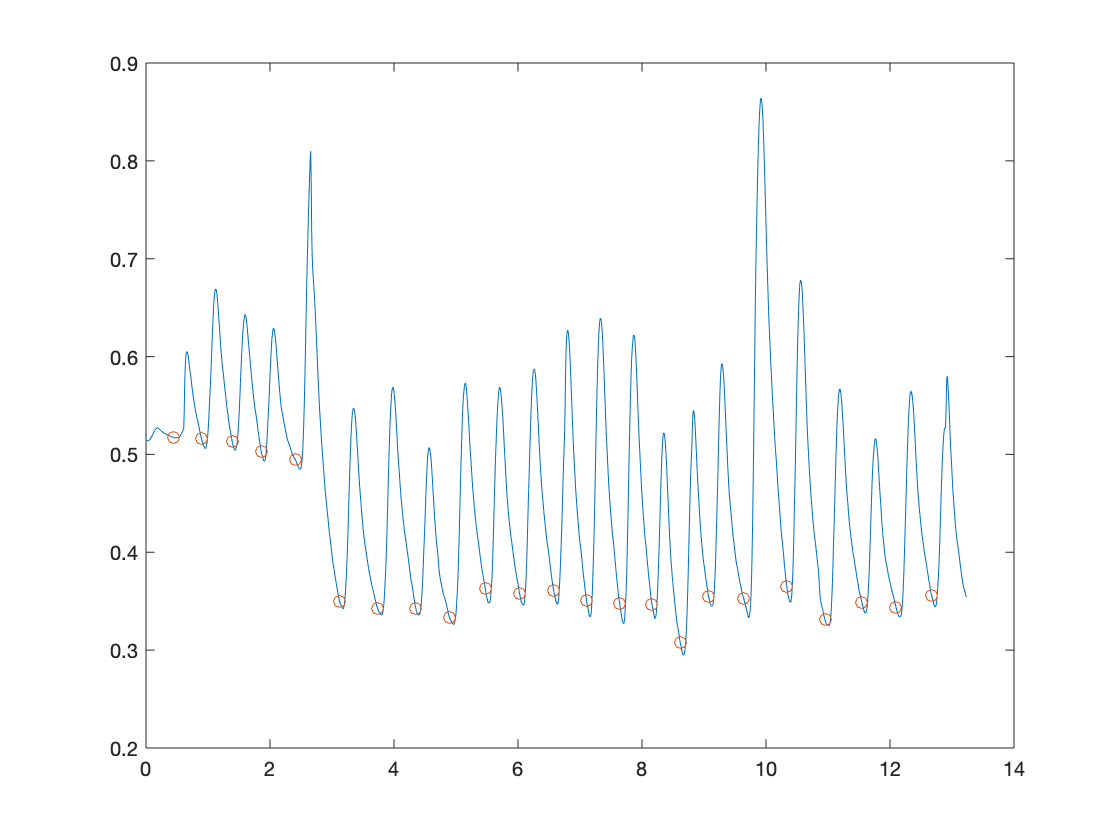

clf
plot(data(:,1), data(:,3))
hold on
scatter(data(beat_locs,1), data(beat_locs,3))